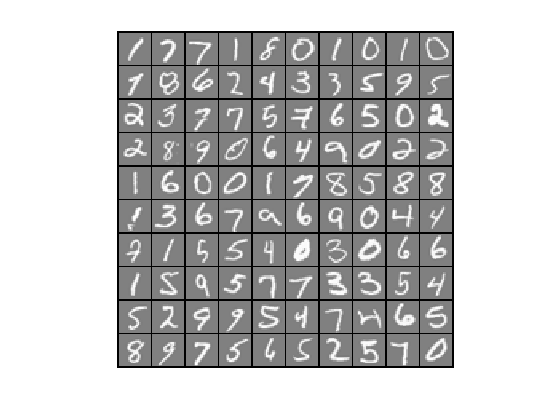

% Load saved matrices from file
load('ex3data1.mat');
% The matrices X and y will now be in your MATLAB environment

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);
displayData(sel);


theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);
lambda_t = 3;
[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);

fprintf('Cost: %f | Expected cost: 2.534819\n',J);

Cost: 2.534819 | Expected cost: 2.534819


fprintf('Gradients:\n'); fprintf('%f\n',grad);

Gradients:
0.146561
-0.548558
0.724722
1.398003


fprintf('Expected gradients:\n 0.146561\n -0.548558\n 0.724722\n 1.398003');

Expected gradients:
 0.146561
 -0.548558
 0.724722
 1.398003

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;
[all_theta] = oneVsAll(X, y, num_labels, lambda);

Iteration     1 | Cost: 2.802128e-01
Iteration     2 | Cost: 9.454389e-02
Iteration     3 | Cost: 5.704641e-02
Iteration     4 | Cost: 4.688190e-02
Iteration     5 | Cost: 3.759021e-02
Iteration     6 | Cost: 3.522008e-02
Iteration     7 | Cost: 3.234531e-02
Iteration     8 | Cost: 3.145034e-02
Iteration     9 | Cost: 3.008919e-02
Iteration    10 | Cost: 2.994639e-02
Iteration    11 | Cost: 2.678528e-02
Iteration    12 | Cost: 2.660323e-02
Iteration    13 | Cost: 2.493301e-02
Iteration    14 | Cost: 2.475211e-02
Iteration    15 | Cost: 2.318421e-02
Iteration    16 | Cost: 2.287050e-02
Iteration    17 | Cost: 2.160258e-02
Iteration    18 | Cost: 2.120371e-02
Iteration    19 | Cost: 2.064125e-02
Iteration    20 | Cost: 2.055695e-02
Iteration    21 | Cost: 2.045466e-02
Iteration    22 | Cost: 2.029177e-02
Iteration    23 | Cost: 2.005296e-02
Iteration    24 | Cost: 1.995949e-02
Iteration    25 | Cost: 1.982849e-02
Iteration    26 | Cost: 1.975129e-02
Iteration    27 | Cost: 1.897815e-02
I

size(all_theta)

ans =    401    10


y(1)

ans = 10

[ones(5000, 1),X]*all_theta

ans =   -37.0036   -7.9520   -9.7180  -21.1467   -6.8963  -13.2397  -12.2817  -11.2523   -6.3629    7.7248
  -29.8383  -10.4695   -9.3367  -22.5752   -4.5682  -19.1604  -11.9323  -14.6788   -9.2279    9.5789
  -35.6269   -8.0371   -7.2773  -19.4422   -7.1252   -9.9160  -14.7444   -4.2700   -6.2460    8.1353
  -43.4741   -7.6729   -9.2384  -18.8355  -11.5070   -7.3461  -14.0771   -9.5665   -8.4853    9.6413
  -46.0068  -12.9760   -8.8638  -25.5991   -5.0802  -36.7338  -16.2443   -9.8247  -11.6486    7.1195
  -43.3932   -8.1005  -15.2252  -26.9674   -7.9460  -21.0333  -15.5345   -3.5272   -9.0413   15.3151
  -41.5449  -16.8647   -2.3220  -26.2282  -16.8580  -27.4664  -12.2619   -6.9293   -7.4795    7.5894
  -18.3628   -0.0042   -7.0095  -20.4751   -1.8436  -18.5256  -15.0490   -5.3957  -16.4826    2.9241
  -44.2162   -8.3144   -6.4214  -24.2992   -7.1728  -18.4478  -11.1986   -3.4445   -8.0520    8.1420
  -34.9534  -12.8739   -0.6104  -20.0214   -6.1827  -23.1157  -11.2848  -10.8396   -6

p=sigmoid([ones(5000, 1),X]*all_theta)

p =     0.0000    0.0004    0.0001    0.0000    0.0010    0.0000    0.0000    0.0000    0.0017    0.9996
    0.0000    0.0000    0.0001    0.0000    0.0103    0.0000    0.0000    0.0000    0.0001    0.9999
    0.0000    0.0003    0.0007    0.0000    0.0008    0.0000    0.0000    0.0138    0.0019    0.9997
    0.0000    0.0005    0.0001    0.0000    0.0000    0.0006    0.0000    0.0001    0.0002    0.9999
    0.0000    0.0000    0.0001    0.0000    0.0062    0.0000    0.0000    0.0001    0.0000    0.9992
    0.0000    0.0003    0.0000    0.0000    0.0004    0.0000    0.0000    0.0285    0.0001    1.0000
    0.0000    0.0000    0.0893    0.0000    0.0000    0.0000    0.0000    0.0010    0.0006    0.9995
    0.0000    0.4989    0.0009    0.0000    0.1366    0.0000    0.0000    0.0045    0.0000    0.9490
    0.0000    0.0002    0.0016    0.0000    0.0008    0.0000    0.0000    0.0309    0.0003    0.9997
    0.0000    0.0000    0.3520    0.0000    0.0021    0.0000    0.0000    0.0000    0.0

[~,index] = max(p,[],2)

index =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10


pred = predictOneVsAll(all_theta, X);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns
in the first matrix matches the number of rows in the second matrix. To operate on
each element of the matrix individually, use TIMES (.*) for elementwise
multiplication.

Error in predictOneVsAll (line 34)
p=sigmoid(X*all_theta');

Related documentation

fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

load('ex3data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
% displayData(X(sel, :));
load('ex3weights.mat'); 

pred = predictl(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

function p1 = predictl(Theta1, Theta2, X)
% Useful values
m = size(X, 1);
num_labels = size(Theta2, 1);

% You need to return the following variables correctly 
p = zeros(size(X, 1), 1);

X = [ones(m, 1) X];
p=sigmoid(X*Theta1');
p = [ones(m, 1) p];
p1=sigmoid(p*Theta2');
[~,p1] = max(p1,[],2);

end
